% figure; hold on;
% colormap jet;
% Current_frames = 950:1200;
% FigColors = MyVaryColor(length(Current_frames));
% my_x_axis = 1:size(RowOverTimeCell{1},2);
% for i = 1:length(Current_frames)
%     plot(my_x_axis-PhediLocation(ismember(frameCount,Current_frames(i))),...
%         RowOverTimeCell{1}(Current_frames(i),:),...
%         'Color',FigColors(i,:));
%     
% end

DoPlots = 0;
preFrames = 300;
postFrames = 4000;
experNum = 1;
eventNum = 6;
[RowOverTimeCell, ~, ~, ~,...
    ~, ~, ~, ~, ~, sg_data, ~,CAM_meta]...
            = analyzeEnlargementAndStrain(experNum, eventNum,DoPlots, preFrames, postFrames);

At least one END is missing: the statement may begin here.


## General stiff

relevanrRowOverTime = RowOverTimeCell{9};
res = 32/(100e-6);    % pix/m
fps = 8e5;        % frames/s

timeCount = [-preFrames:postFrames]/fps;
spatialVec = (0:(size(RowOverTimeCell{1},2)-1))/res;


## calculate phedis

% phedislocationInPix = phedisDB(2);
phedislocationInPix = Movie_findTrenches(relevanrRowOverTime(270,:));
tic;
[frameCount, PhediLocationPix, slopeIncline] = Movie_calculate_continues_shift(relevanrRowOverTime, 170, 700, phedislocationInPix);
toc;

Elapsed time is 576.973223 seconds.


%--- transform units:
PhediLocation = (PhediLocationPix-1)/res;
measuredPhedisFromPlot = (phedislocationInPix-1)/res;
timeVec= timeCount(frameCount);


## plot heat map and phedis dynamics

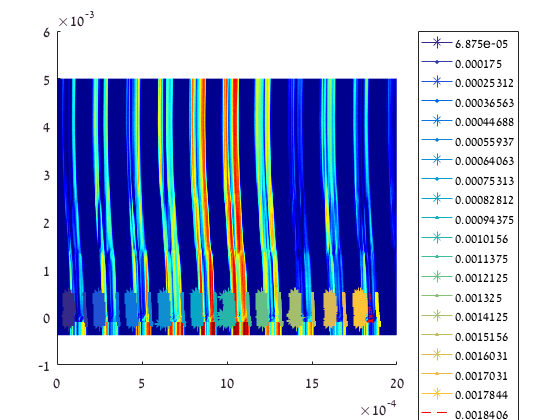

FigColors = MyVaryColor(size(PhediLocation,2));
figure; hold on;
colormap default;
imagesc([spatialVec(1) spatialVec(end)],[timeCount(1) timeCount(end)],relevanrRowOverTime);
colormap jet
for i = 1:size(PhediLocation,2)
    if slopeIncline(i)>0
        plot(PhediLocation(:,i)+measuredPhedisFromPlot(i),timeVec,...
            '*-','Color',FigColors(i,:));
    elseif slopeIncline(i)<0
        plot(PhediLocation(:,i)+measuredPhedisFromPlot(i),timeVec,...
            '.-','Color',FigColors(i,:));
    else
        plot(PhediLocation(:,i)+measuredPhedisFromPlot(i),timeVec,...
            'r--');
    end
end
LGND = cellfun(@num2str,num2cell(measuredPhedisFromPlot),'UniformOutput',0);
LGND = cat(1,LGND,{'row over time'});
legend(LGND,'location','eastoutside');

## plot only phedi

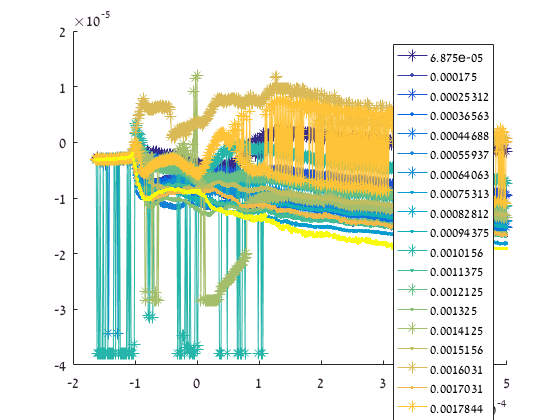

figure; hold on;
colormap jet
for i = 1:size(PhediLocation,2)
    if slopeIncline(i)>0
        plot(timeVec,PhediLocation(:,i),...
            '*-','Color',FigColors(i,:));
    elseif slopeIncline(i)<0
        plot(timeVec,PhediLocation(:,i),...
            '.-','Color',FigColors(i,:));
        else
%         plot(timeVec,PhediLocation(:,i),...
%             'r--');
    end
end
LGND = cellfun(@num2str,num2cell(measuredPhedisFromPlot),'UniformOutput',0);
legend(LGND);

## **phedi velocity**

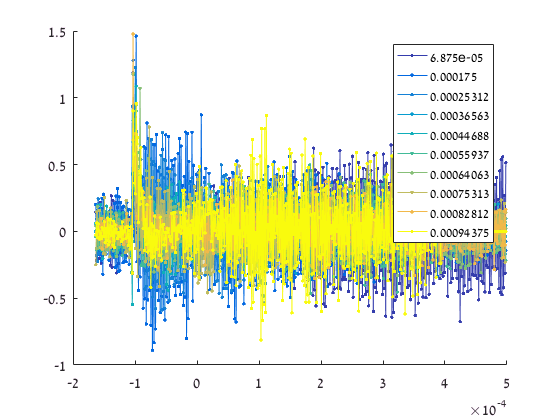

Cf = 105;        %(m/s)
PhediVelocity = -diff(PhediLocation,[],1)./diff(repmat(timeVec',1,size(PhediLocation,2)),[],1);
velocityTime = movmean(timeVec,2,'Endpoints','discard');

figure; hold on;
colormap jet
for i = 1:size(PhediVelocity,2)
    if slopeIncline(i)>0
%         plot(velocityTime,PhediVelocity(:,i),...
%             '*-','Color',FigColors(i,:));
    elseif slopeIncline(i)<0
        plot(velocityTime,PhediVelocity(:,i),...
            '.-','Color',FigColors(i,:));
        else
%         plot(velocityTime,PhediVelocity(:,i),...
%             'r--');
    end
end
LGND = cellfun(@num2str,num2cell(measuredPhedisFromPlot),'UniformOutput',0);
legend(LGND);

## plot crossection


% colormap jet;
% Movie_PlotRowFromHeatMap(relevanrRowOverTime,850:10:(850+1750));